# Plotting In MATLAB

There are numerous plotting features within MATLAB. The most commonly used function is the *plot* command, which creates a 2-D plot given a series of (x,y) cooridnate pairnings. 

## *Plot*

### Basic Plot

Below is some example code of creating a plot. Suposse we want to model the height a rocket is at for 10 seconds after  being thrown straight up into the air (ignoring air resistance).

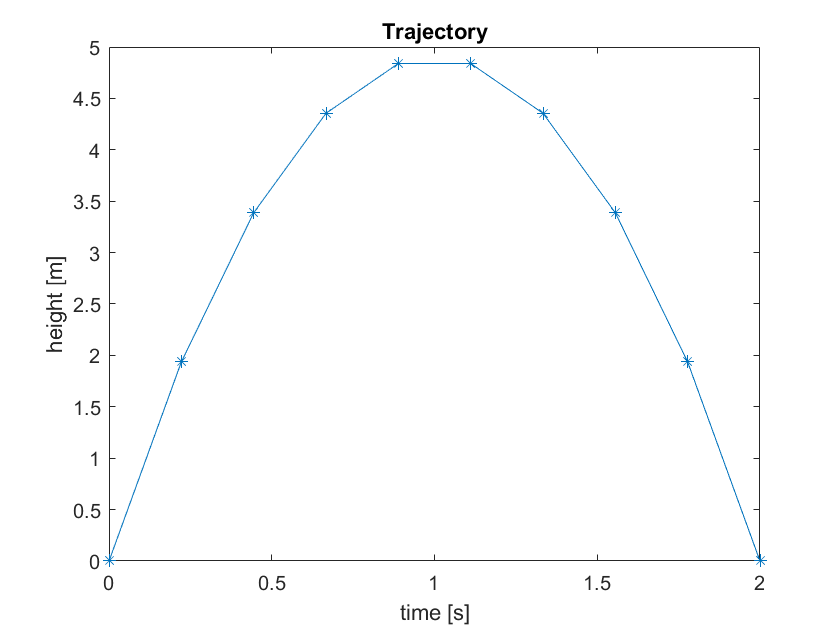

t = linspace(0,2,10);  % time 
y = -4.9*t.^2+9.8.*t;    % height in m

figure(1)
plot(t,y,'-*')
title('Trajectory')
xlabel('time [s]')
ylabel('height [m]')

Note how plot draws a straight line between two points when plotting. To prevent this choppy look, you will need to increase the number of calcualted points to make the resulting plot appear more smooth. Be careful about adding too many additional poinjts as this will make your code run much slower. To adjust  the number of points that get calculated, you need to modify the third parameter, the number of points to be made, in the linspace function.

### Plot Multiple Items

Now suppose that we want to plot the trajectories from multiple rockets on the same plot. We can do that in the follwoing way

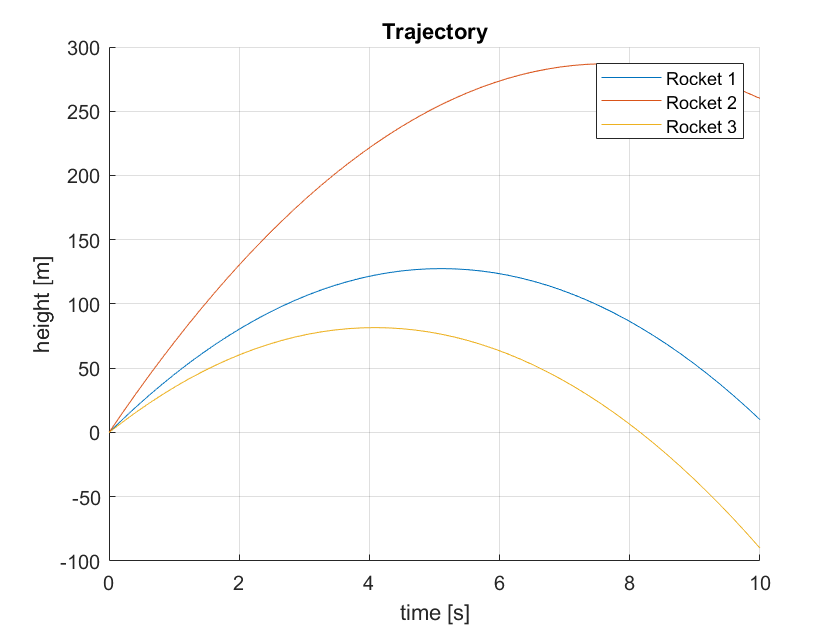

t = linspace(0,10,50);  % time
y1 = -4.9*t.^2+50.*t;   % rocket 1 height in m
y2 = -4.9*t.^2+75.*t;   % rocket 2 height in m 
y3 = -4.9*t.^2+40.*t;   % rocket 3 height in m

figure(2)
hold on 
grid on 
plot(t,y1,t,y2,t,y3)
title('Trajectory')
legend('Rocket 1', 'Rocket 2','Rocket 3')
xlabel('time [s]')
ylabel('height [m]')
hold off

Entries in the *legend *command must be in the same order as they were plotted, otherwise the labels will be mismatched.

*Figure *is used to allow you to create mutliple independent plots. 

The *grid *guide adds a grid to the current plot.

The *hold *command allows for multiple things to be plotted without previously plotted items from being over written.